clear; clc
n = 1;
xx = 100:100:100000;

halton_results = zeros(length(xx), 4);
lhs_results = zeros(length(xx), 4);
sobol_results = zeros(length(xx), 4);

for i = xx
    aa = convergence_halton(i);
    halton_results(n, 1) = aa(1,1);
    halton_results(n, 2) = aa(1,2);
    halton_results(n, 3) = aa(2,1);
    halton_results(n, 4) = aa(2,2);

    bb = convergence_lhs(i);
    lhs_results(n, 1) = bb(1,1);
    lhs_results(n, 2) = bb(1,2);
    lhs_results(n, 3) = bb(2,1);
    lhs_results(n, 4) = bb(2,2);

    cc = convergence_sobol(i);
    sobol_results(n, 1) = cc(1,1);
    sobol_results(n, 2) = cc(1,2);
    sobol_results(n, 3) = cc(2,1);
    sobol_results(n, 4) = cc(2,2);    
    n = n+1;
end

convTime_lhs = zeros(1,4);
convTime_halton = zeros(1,4);
convTime_sobol = zeros(1,4);

parfor i = 1:length(halton_results)-1
    for j = 1:4
        a = halton_results(i, j);
        ap = halton_results(i+1, j);
        conv_rate_halton(i, j) = (ap - a)/a;

        b = lhs_results(i, j);
        bp = lhs_results(i+1, j);
        conv_rate_lhs(i,j) = (bp-b)/b;

        c = sobol_results(i, j);
        cp = sobol_results(i+1, j);
        conv_rate_sobol(i, j) = (cp - c)/c;
    end
end
for j = 1 :4
    n = 1; m = 1; l = 1;
    for i = 1:length(halton_results)-1    
        if i > 10 
            a = mean(abs(conv_rate_halton(i-10:i, j)));
            % Convergence is set as 1% percent diff for last 10 results
            if a <= 0.01 && n == 1 
                convTime_halton(j) = i;
                n = n+1;
            end
            b = mean(abs(conv_rate_lhs(i-10:i, j)));
            if b <= 0.01 && m == 1
                convTime_lhs(j) = i;
                m = m+1;
            end
            c = mean(abs(conv_rate_sobol(i-10:i, j)));
            if c <= 0.01 && l == 1
                convTime_sobol(j) = i;
                l = l+1;
            end
        end
    end
end
convTime_lhs

convTime_lhs =    385   671   453   564


convTime_halton

convTime_halton =     23    39    12    21


convTime_sobol

convTime_sobol =     26    32    13    31



NumSimConv_lhs = 1000 + (convTime_lhs-1)*100

NumSimConv_lhs =        39400       68000       46200       57300


NumSimConv_halton = 1000 + (convTime_halton-1)*100

NumSimConv_halton =         3200        4800        2100        3000


NumSimConv_sobol = 1000 + (convTime_sobol-1)*100

NumSimConv_sobol =         3500        4100        2200        4000


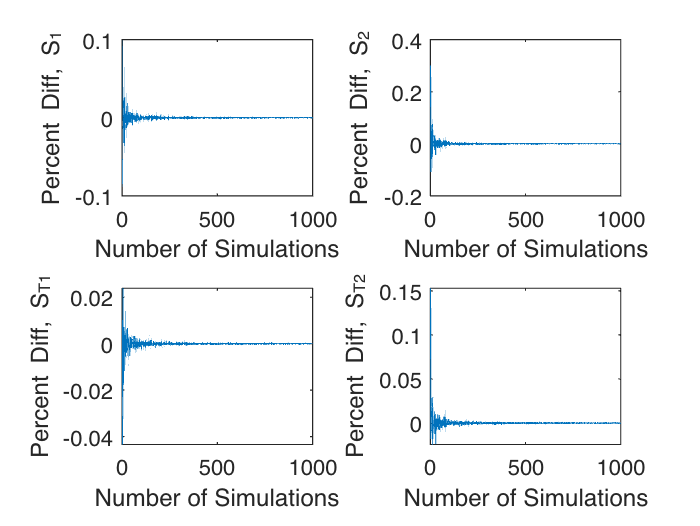


% Plot of convergence rate of sobal indices
figure
subplot(2,2,1)
plot(1:length(halton_results)-1, conv_rate_halton(:, 1))
ylabel('Percent Diff, S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(1:length(halton_results)-1, conv_rate_halton(:, 2))
ylabel('Percent Diff, S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(1:length(halton_results)-1, conv_rate_halton(:, 3))
ylabel('Percent Diff, S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(1:length(halton_results)-1, conv_rate_halton(:, 4))
ylabel('Percent Diff, S_{T2}')
xlabel('Number of Simulations')

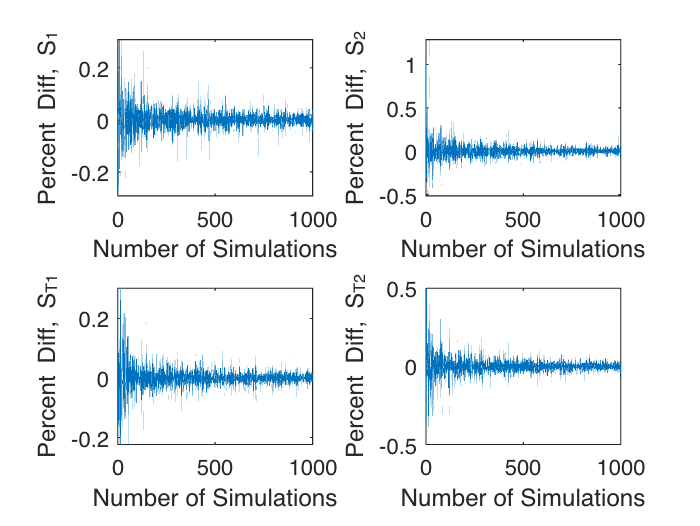


figure 
subplot(2,2,1)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 1))
ylabel('Percent Diff, S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 2))
ylabel('Percent Diff, S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 3))
ylabel('Percent Diff, S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 4))
ylabel('Percent Diff, S_{T2}')
xlabel('Number of Simulations')

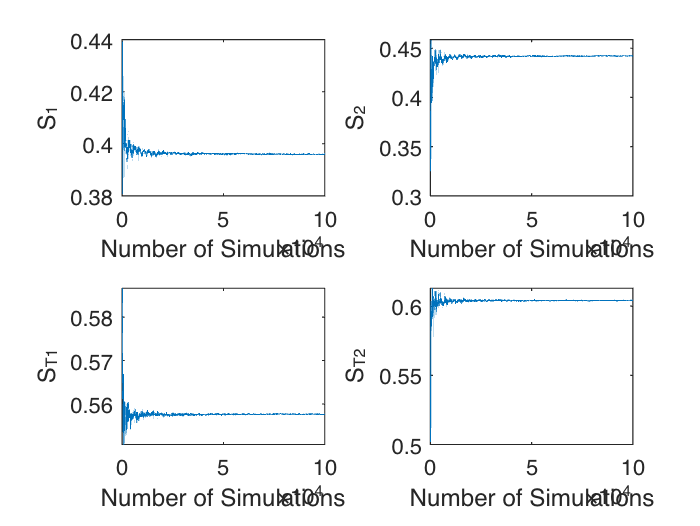


% Plot of sobal indices values vs number of simulations
figure
title('Halton Sequance')
subplot(2,2,1)
plot(xx, halton_results(:,1))
ylabel('S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(xx, halton_results(:,2))
ylabel('S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(xx, halton_results(:,3))
ylabel('S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(xx, halton_results(:,4))
ylabel('S_{T2}')
xlabel('Number of Simulations')

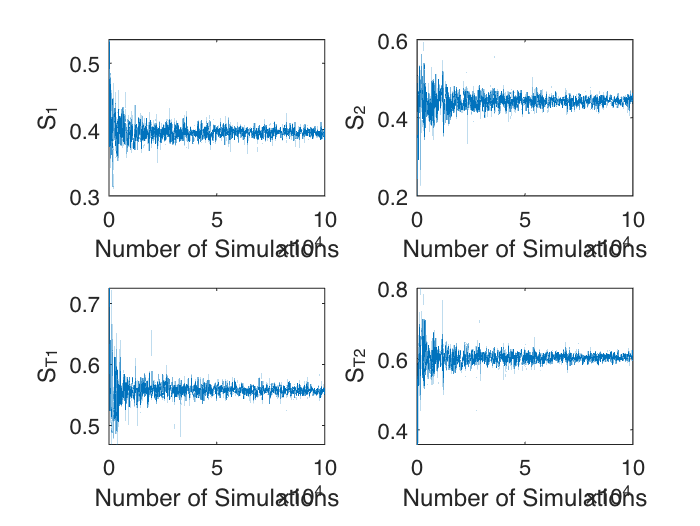


figure
subplot(2,2,1)
plot(xx, lhs_results(:,1))
ylabel('S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(xx, lhs_results(:,2))
ylabel('S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(xx, lhs_results(:,3))
ylabel('S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(xx, lhs_results(:,4))
ylabel('S_{T2}')
xlabel('Number of Simulations')

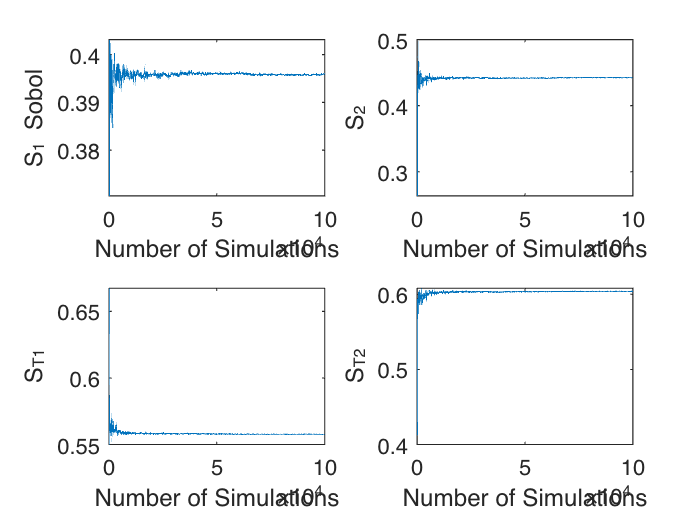

figure
subplot(2,2,1)
plot(xx, sobol_results(:,1))
ylabel('S_1 Sobol')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(xx, sobol_results(:,2))
ylabel('S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(xx, sobol_results(:,3))
ylabel('S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(xx, sobol_results(:,4))
ylabel('S_{T2}')
xlabel('Number of Simulations')